#     Ecuaciones lineales de primer orden  

# Problemas de valor inicial

## Adaptive and  Multistep methods 

## Stiff systems and Implicit methods

### Epidemia

The following ODEs have been proposed as a model of an epidemic:


$$\frac{\mathrm{d}}{\mathrm{d}t}S=-a\;S\;I$$



$$\frac{\mathrm{d}}{\mathrm{d}t}I=a\;S\;I-r\;I$$



$$\frac{\mathrm{d}}{\mathrm{d}t}R=r\;I$$


where S = the susceptible individuals, I = the infected, R = the recovered, a = the infection rate, and r = the recovery rate. A city has 10,000 people, all of whom are susceptible. If a single infectious individual enters the city at t = 0, compute the progression of the epidemic until the number of infected individuals falls below 10. Use the following parameters: a = 0.002/(person · week) and r = 0.15/d.

Develop time-series plots of all the state variables.

Suppose that after recovery, there is a loss of immunity that causes recovered individuals to become susceptible.

This reinfection mechanism can be computed as ρR, where ρ = the reinfection rate. Modify the model to include this mechanism and repeat the computations using ρ = 0.03/d.

### Variable step size

Solve the following ODE from t=0 to 4, where y(0)=0.5. Obtain the solution for a relative tolerance of ${10}^{-5}$:


$$\frac{\mathrm{d}}{\mathrm{d}t}y=10e^{-\left({\left(t-2\right)}^2 /2{\left(0\ldotp 075\right)}^2 \right)} -0\ldotp 6y$$


RelTol=10e-5;
y0=0;
t0=0.5;
tf=4;
f=@(t,y) 10*e(-(((t-2)^2)/(2*(0.075)^2)))-0.6*y;
h=0.1;
% [t,y] = miODE23(f,t0,h,tf,y0,RelTol)

Solve the initial value problem within a relative tolerance of ${10}^{-6}$:

$y^{\prime } =t\;y+t^3$         $y\left(0\right)=1$          t in [0,1]

RelTol=10e-6;
y0=0;
t0=0;
tf=1;
f=@(t,y) t*y+t^3;
h=0.1;
% [t,y] = miODE23(f,t0,h,tf,y0,RelTol)

### Mutistep 

Solve the initial value problem:

$y^{\prime } =\frac{1}{2}\left(1+x\right)y^2$         $y\;\left(0\right)=1$          t in [0,1]

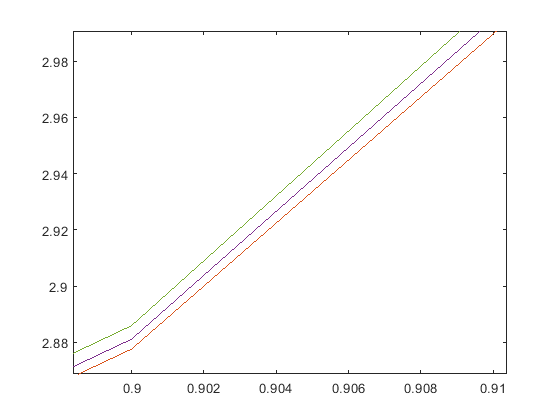

f=@(t,y) (1/2)*(1+t)*y^2;
t0=0;
tf=1;
y0=1;
h=0.1;
M=milne(f,t0,h,tf,y0);
plot(M(:,1),M(:,2))
hold on
A=abm(f,t0,h,tf,y0);
plot(A(:,1),A(:,2))

hold off

Solve the initial value problem:

$y^{\prime } =\frac{-2y}{1+t}$         $y\;\left(0\right)=2$          t in [0,2.5]

%

### Stiff equations

A problem is stiff if the solution being sought varies slowly, but there are nearby solutions that vary rapidly, so the numerical method must take small steps to obtain satisfactory results.

Apply the Euler and Backward Euler methods to the initial value problem

$y^{\prime } =y+8y^2 -9y^3$         $y\;\left(0\right)=0\ldotp 5$          t in [0,3]

function M=milne(f,t0,h,tf,y0)

t =     0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.3000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000


y = 	1.0e+-40 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0074    0.0460    0.1141    0.1566    0.1708    0.1719    0.1719         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


    
    n=length(y0);
    t=t0:h:tf;
    m=length(t);
    tol=eps;
    y=zeros(n,m);
    jMax=100;
    
    s= t0+3*h;
    [tS, yS]=RK4(f,t0,h,s,y0);
    t(1:4)=tS;
    y(:,1:4)=yS;
    
    for i=4:m-1
       %Predictor
       y(:,i+1)= y(i-3)+(4*h/3)*(2*f(t(i),y(i))-f(t(i-1),y(i-1))+2*f(t(i-2),y(i-2)));
       j=1;
       cond=true;
       while cond
           %Corrector
           yp=y(:,i+1);
           y(:,i+1)=y(:,i-1)+(h/3)*(f(t(i-1),y(i-1))+4*f(t(i),y(i))+f(t(i+1),yp));
           j=j+1;
           cond=j<jMax && norm((y(:,i+1)-yp)/y(:,i+1),inf)>tol;
       end
    end
    
    M=[t' y'];
end
function M=abm(f,t0,h,tf,y0)
    
    n=length(y0);
    t=t0:h:tf;
    m=length(t);
    tol=eps;
    y=zeros(n,m);
    jMax=100;
    
    s= t0+3*h;
    [tS, yS]=RK4(f,t0,h,s,y0);
    t(1:4)=tS;
    y(:,1:4)=yS;
    
    for i=4:m-1
       %Predictor
       y(:,i+1)= y(i)+h*((55/24)*f(t(i),y(i))-(59/24)*f(t(i-1),y(i-1))+(37/24)*f(t(i-2),y(i-2))-(9/24)*f(t(i-3),y(i-3)));
       j=1;
       cond=true;
       while cond
           %Corrector
           yp=y(:,i+1);
           y(:,i+1)=y(:,i)+h*((9/24)*f(t(i+1),yp)+(19/24)*f(t(i),y(i))- ...
               (5/24)*f(t(i-1),y(:,i-1))+(1/24)*f(t(i-2),y(:,i-2)));
           j=j+1;
           cond=j<jMax && norm((y(:,i+1)-yp)/y(:,i+1),inf)>tol;
       end
    end
    
    M=[t' y'];
end
function [t,y] = miODE23(f,t0,h,tf,y0,RelTol)
    Max=1000;
    t=t0:h:tf;
    n=length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    pow=1/3;
    cond=true;
    i=1;
    s1=f(t(:,i),y(:,i));
    
    while cond
        s2=f(t(i)+h/2,y(:,i)+(s1/2)*h);
        s3=f(t(i)+h*3/4,y(:,i)+(s2*3/4)*h);
        y(:,i+1)=y(:,i)+(h/9)*(2*s1+3*s2+4*s3);
        s4=f(t(i+1),y(:,i+1));
        e=(-5*s1+6*s2+8*s3-9*s4)*h/72;
        err=norm(e/y(:,i+1),inf);
        if err<RelTol
            
            t(i)=t(i+1);
            y(:,i)=y(:,i+1);
            s1=s4;
            i=i+1;
        end
        s=(RelTol/err)^pow;
        h=s*h;
        cond=t(i+1)<tf && i<Max;
    end


end

function [t,y] = RK4(f,t0,h,tf,y0)

    % Initialize the output solution arrays.
    t=t0:h:tf;
    n=length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    
    % Compute x an y by integrating the ODE system using Huen's method.
    cond=true;
    i=1;

    while cond
        k1=f(t(i),y(:,i));
        k2=f(t(i)+h/2,y(:,i)+(k1/2)*h);
        k3=f(t(i)+h/2,y(:,i)+(k2/2)*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        the=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+the*h;
        i=i+1;
        cond=i<n;
    end


end
